# Generating Cell Meshes and Calculating Metrics

In this script we generate cell surface meshes for the taste cells listed in the idT table (found in the [Lysosome Analysis folder](matlab:open('./idT.mat'))). These are cells that have had their lysosomes segmented. 

REQUIREMENTS: 

- ManifoldPlus [https://github.com/hjwdzh/ManifoldPlus](https://github.com/hjwdzh/ManifoldPlus) 

- pyMeshFix: [https://pymeshfix.pyvista.org](https://pymeshfix.pyvista.org)

- Mathworks Lidar Toolbox

- MatGeom Toolbox (meshVolume function)

## Overview

We use three mesh-generating steps: The first step, Alpha Shape, generates the base mesh. The following steps, manifoldPlus and MeshFix, plug up any holes in the original mesh to generate a watertight mesh. Meshes for each stage are saved in the cellMeshes folder. Note: due to the complexity of the cells, most meshes are not completely watertight. Employing the secondary mesh steps ensures most holes in the mesh are closed and overall improved volume calculation. 

Meshes are then visually inspected, and the best Mesh for cell is selected.

Metrics, such as Volume and Surface area, are then calculated from the best mesh and saved in the ***cellT*** table. 

General Impressions for each Mesh Method:

- **AlphaShape** generates the most representative shape, but the surface may be riddled with holes, which  significantly affects the volume calculation.  While these holes can be closed up by adjusting AlphaShape alpha setting, the resultant mesh is less representative of the cell's overall morphology (all the fine details get overly smoothed over) and the volume calculations maybe adversely affected. So, we call the **alphaShape **function without any alpha setting to ensure the best reconstruction of cell morphology

- **manifoldPlus** does a good job of closing up small holes while maintaining the cell's overall morphology. While, there is some degradation in the ultrastructure of the cell, volume calculations are improved.

- **MeshFix** is needed to close up large holes or holes not sealed up by manifoldPlus. However, This method may result in some noticeable degradation in the ultrastructure of the cell, but the overall volume calculation remains robust

## Setup

### Add Path

Cell Meshes will be created and stored here. Update manifoldPlus path for your local installation (../build/manifold)

clearvars -except paths proj

#### Set manifoldPlus path if needed

paths.manifoldPlus = "/Users/ernesto/github/ManifoldPlus/build/manifold"

paths = struct with fields:
          project: "/Users/ernesto/github/Dying_Taste_Cell_analysis"
         lysosome: "/Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis"
           nuclei: "/Users/ernesto/github/Dying_Taste_Cell_analysis/Nuclei Analysis"
       supportfns: "/Users/ernesto/github/Dying_Taste_Cell_analysis/Support Functions"
         cellMesh: "/Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/cellMeshes"
    dyingCellMesh: "/Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/dyingMeshes"
     manifoldPlus: "/Users/ernesto/github/ManifoldPlus/build/manifold"
      reconstruct: "/Users/ernesto/Documents/WORK/Research/Finger Lab/Dying Cell Project/reconstruct data"
           series: "/Users/ernesto/Documents/WORK/Research/Finger Lab/Dying Cell Project/reconstruct data/Courtney_TF21"


### Load necessary variables

Vertices imported from the Reconstruct data are stored in the VL table. The idT table contains identifying information, like the name of the cell, its type (e.g, I, II, or III), and its health (e.g. healthy, early dying, late dying). 

VL = loadProjectTables(paths)

## Generate Cell Meshes

The function **generateCellMeshes** generates cell meshes using alphaShape, manifoldPlus, and MeshFix. The function automatically saves these surface meshes as OBJ files in the cell Meshes folder. The function returns a table, ***meshT***, with the following fields

- **Cell**: name of cell

- **VolAS, VolMP, VolFX: ** the calculated volumes for each surface mesh

- **Method: **The surface mesh to use for calculating cell metrics. By default, the method is set to "MP" unless VolAS is greater than the other two volumes. That being said, meshes need to be visually inspected to ensure the best mesh method is selected.

meshT = generateCellMeshes(VL, paths);

meshT file found and loaded. Using this table for the analysis.##################### Arguments #####################
depth: 6.
input: /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/cellMeshes/TB1_AP44_EM_as.obj.
output: /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/cellMeshes/TB1_AP44_EM_mp.obj.
#####################################################
vertex number: 11722    face number: 24666
Initialize AABB Tree...
Build Halfedges...
Split non-manifold vertices...
Rebuild Halfedges...
Gauss-seidel update...
Iter 0 with active vertex number 890    
Iter 1 with active vertex number 890    
Iter 2 with active vertex number 700    
Iter 3 with active vertex number 283    
Iter 4 with active vertex number 235    
Iter 5 with active vertex number 222    
Iter 6 with active vertex number 209    
Iter 7 with active vertex number 189    
Iter 8 with active vertex number 186    
Iter 9 with active vertex number 188    
Iter 10 with active vertex number 178  

### Save Mesh T

save(meshT.Properties.UserData.filePath,"meshT");

### Generate only a subset of meshes

mt = generateCellMeshes(VL,idT(1,:),paths) % e.g. just first row in idT

##################### Arguments #####################
depth: 6.
input: /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/cellMeshes/TB1_AP16_EM_as.obj.
output: /Users/ernesto/github/Dying_Taste_Cell_analysis/Lysosome Analysis/cellMeshes/TB1_AP16_EM_mp.obj.
#####################################################
vertex number: 8353    face number: 16764
Initialize AABB Tree...
Build Halfedges...
Split non-manifold vertices...
Rebuild Halfedges...
Gauss-seidel update...
Iter 0 with active vertex number 1212    
Iter 1 with active vertex number 1212    
Iter 2 with active vertex number 867    
Iter 3 with active vertex number 293    
Iter 4 with active vertex number 233    
Iter 5 with active vertex number 202    
Iter 6 with active vertex number 186    
Iter 7 with active vertex number 167    
Iter 8 with active vertex number 147    
Iter 9 with active vertex number 141    
Iter 10 with active vertex number 142    
Iter 11 with active vertex number 140    
Iter 12 with acti

## Load meshT from previous runs

load(fullfile(paths.cellMesh,"meshT.mat"),"-mat","meshT")

## Inspect Cell Meshes

Once **generateCellMeshes** is complete, it is critical to inspect all of the meshes, especially those that have radically different volume calculations between the various methods.  

In this code block, you select the row in meshT that you would like to inspect and the function **displayCellMeshes** will display the corresponding surface meshes using the  **surfaceMeshShow** function. 

Method Guidelines: 

- If VolAS is equal or greater than the other two volumes, use the AS method

- If VolFX is significantly greater than the other two volumes, use the FX method. There is likely  a large hole somewhere in the mesh

Note: you change the set mesh method in the next code block

1. TB1_AP40_EM_as.obj - 0


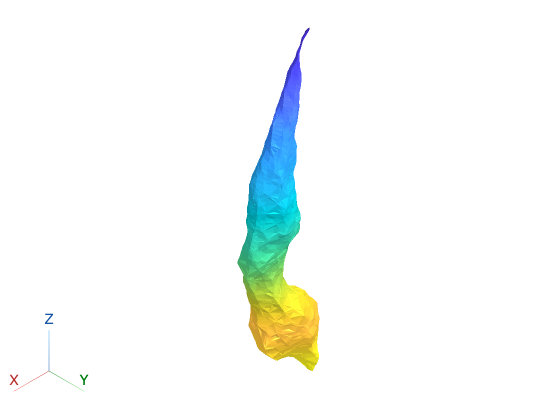

2. TB1_AP40_EM_fx.obj - 0
3. TB1_AP40_EM_mp.obj - 0


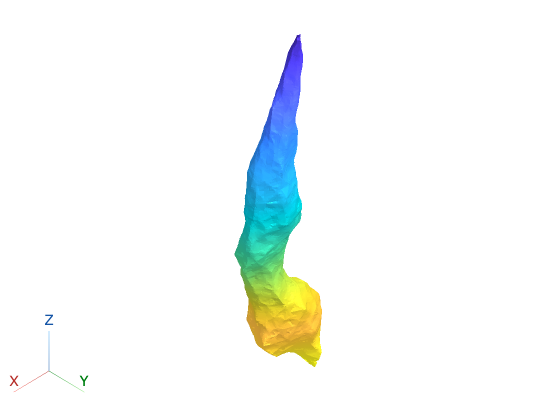

ans =   LinkProp with properties:

          Enabled: 'on'
    PropertyNames: {'CameraPosition'  'CameraZoom'}
          Targets: [1×3 Viewer3D]


meshT_row = 12; % selected row
hvwr = displayCellMeshes(meshT.Cell(meshT_row),paths.cellMesh);

### Overlay AS and MP meshes

to double-check if needed

hp = overlayCellMeshes(paths, meshT.Cell(meshT_row));

### Update method for selected row

The method will be used to indicate which cell mesh is used to calculate the cell metrics like volume and surface in the next step.

method = "fx";
meshT.Method(meshT_row) = method;

save(meshT.Properties.UserData.path,"meshT")
fprintf('%d. %s changed to %s.\n',meshT_row,meshT.Object(meshT_row),method)

## Manual Cell Reconstruction

as needed

cellName = "TB1_AP40_EM"

cellName = "TB1_AP40_EM"

polarity = 1;
aRadius = 2;
[mt, meshT_row] = generateSingleCellMesh(VL,meshT,paths, cellName, polarity, aRadius);

        Cell         Type    Health     Method    Polarity    AlphaRadius    VolAS     VolMP    VolFX 
    _____________    ____    _______    ______    ________    ___________    ______    _____    ______

    "TB1_AP40_EM"    "II"    "early"     "mp"        1            NaN        266.86    315.3    404.68

        Cell         Type    Health     Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX
    _____________    ____    _______    ______    _

#### update meshT

meshT(meshT_row,:) = mt;

#### save meshT

save(meshT.Properties.UserData.filePath,"meshT");

#### Flip Polarity for the following cells

cells2flip = ["TB1_AP37_EM";...
    "TB2_T1C-05_cw";...
    "TB1_AP14_EM";...
    "TB2_T2Cell03_CM_LES";...
    "TB2_T2C-10_cw";...
    "TB2_T2C-01_FR";...
    "TB1_AP13_EM";...
    "TB2 Nucleus_04_cw_cell-ry";...

Error using generate_cellMesh_cellT>generateSingleCellMesh (line 154)
Invalid argument at position 6. Value must be scalar or empty.

    "TB2 Nucleus_26_cw_IV-ry";...
    "TB2_T3C-08_cw";...
    "TB2_T3C-14_FR";...
    "TB2_t3cell02_CM_RSL";...

cellName = "TB3_TC02"

    "TB2_TCdying-01_cw";];

    Cell    Type    Health    Method    Polarity    AlphaRadius    VolAS    VolMP    VolFX
    ____    ____    ______    ______    ________    ___________    _____    _____    _____




Error using  .  (line 507)
To assign to or create a variable in a table, the number of rows must match the height of the table.

Error in generate_cellMesh_cellT>generateSingleCellMesh (line 169)
mt.Polarity = Polarity; % flip cell up


la = ismember(meshT.Cell, cellNames2flip);
idc = find(la);

for n=idc'
    cellName = meshT.Cell(n);

        Cell         Type      Health      Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    _____________    _____    _________    ______    ________    ___________    ______    ______    ______

    "TB1_AP31_EM"    "III"    "healthy"     "mp"        -1            2         226.66    560.82    560.67

        Cell         Type      Health      Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    _____________    _____    _________    ______

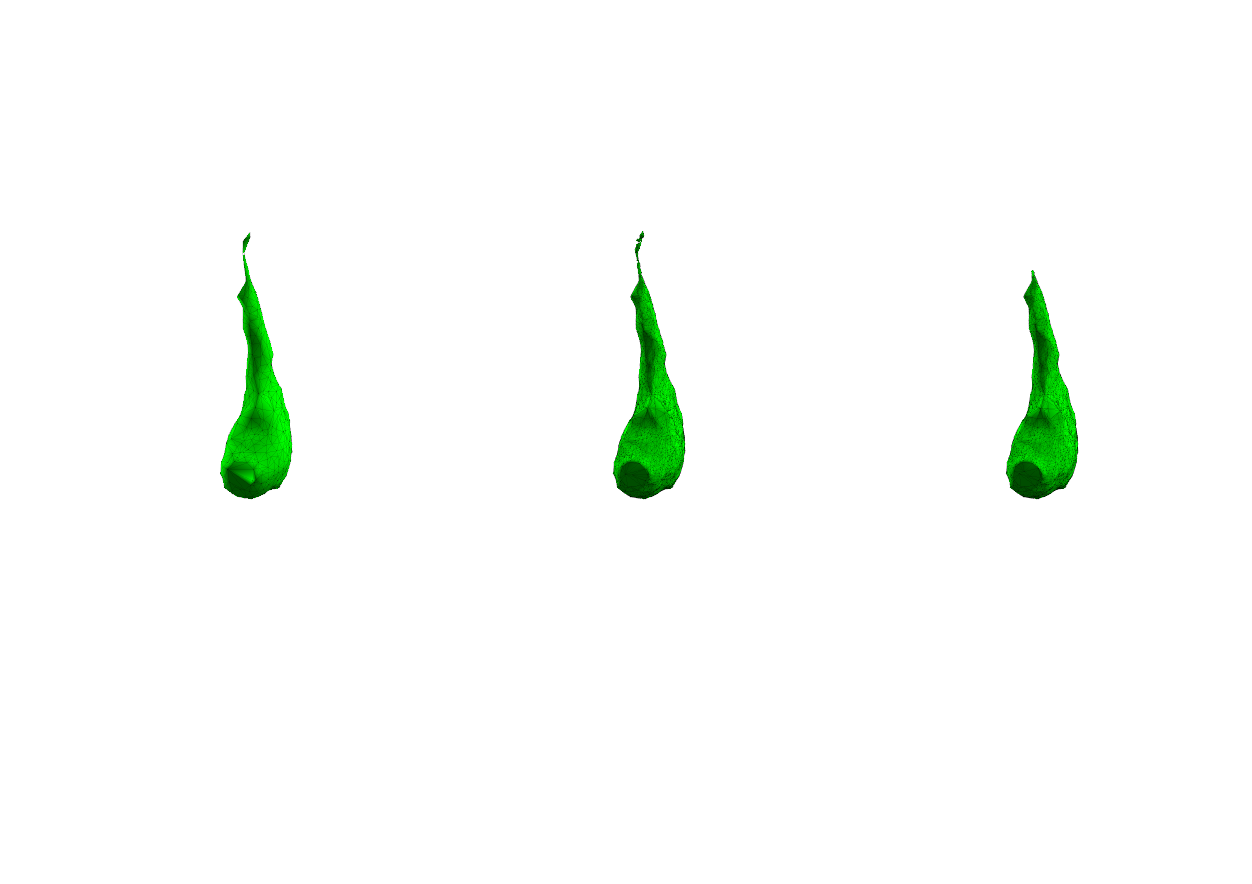

    aR = meshT.AlphaRadius(n);
    [mt, meshT_row] = generateSingleCellMesh(VL,meshT,paths, cellName, -1, aR);
    meshT(meshT_row,:)=mt;
end

### TB1_AP51_EM

Can't close hole — too large

cellName = "TB1_AP51_EM"

volFX =        560.67


[mt, meshT_row] = generateSingleCellMesh(VL,meshT,paths, cellName, 1, nan);

#### Display results

ax = plot_cell_meshes(mt);
set(ax,'View',[-45 0])

         Cell          Type      Health      Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    _______________    _____    _________    ______    ________    ___________    ______    ______    ______

    "TB2_T3C-17_cw"    "III"    "healthy"     "mp"        1            NaN        991.22    990.96    988.56

         Cell          Type      Health      Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    _______________    _____    _________    

### TB1_AP31_EM

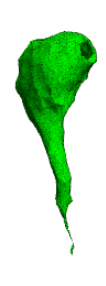

 Has a huge hole in it with the default settings (no alphaShape second input). 

Optimal Settings:

- AlphaRadius of 2 closes the hole

- Polarity of -1 flips the cell

- MP is now  best method for this cell

#### Adjust mesh generation values

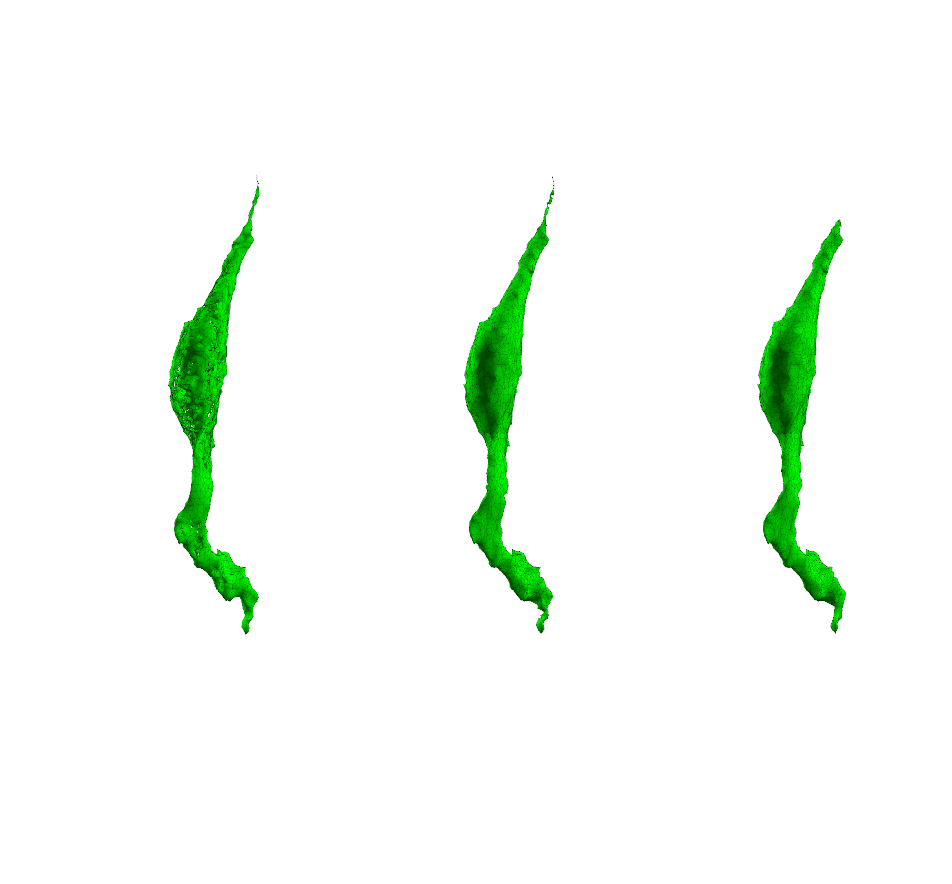

cellName = "TB1_AP31_EM";
[mt, meshT_row] = generateSingleCellMesh(VL,meshT,paths, cellName, -1, 2);

#### Display results

ax = plot_cell_meshes(mt);
set(ax,'View',[-45 0])

- hole closed

#### update meshT

meshT(meshT_row,:) = mt;

### `TB2_T3C-17_cw`

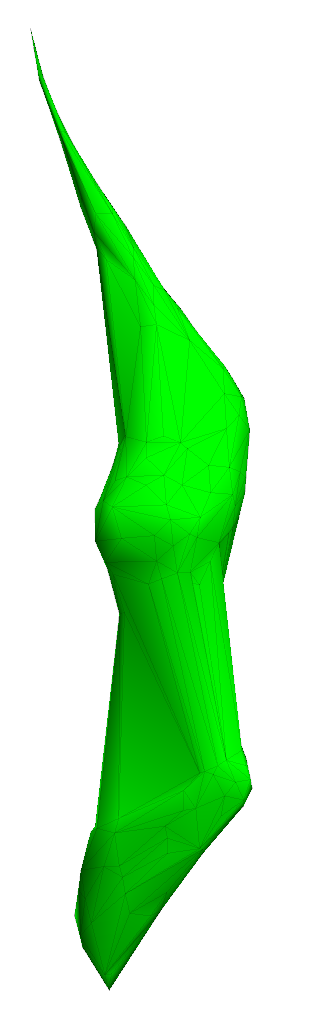

`Reconstruction looks too simplistic. `Calling alphaShape with an alpha radius of 0.5 greatly improves the reconstruction. MP looks like the best method

cellName = "TB2_T3C-17_cw";

         Cell          Type    Health     Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    _______________    ____    _______    ______    ________    ___________    ______    ______    ______

    "TB2_T2C-03_cw"    "II"    "early"     "mp"        1            NaN        1881.8    1883.1    1881.9

         Cell          Type    Health     Method    Polarity    AlphaRadius    VolAS     VolMP     VolFX 
    _______________    ____    _______    ______

[mt, meshT_row] = generateSingleCellMesh(VL,meshT,paths, cellName, 1, 0.5);

#### Display results

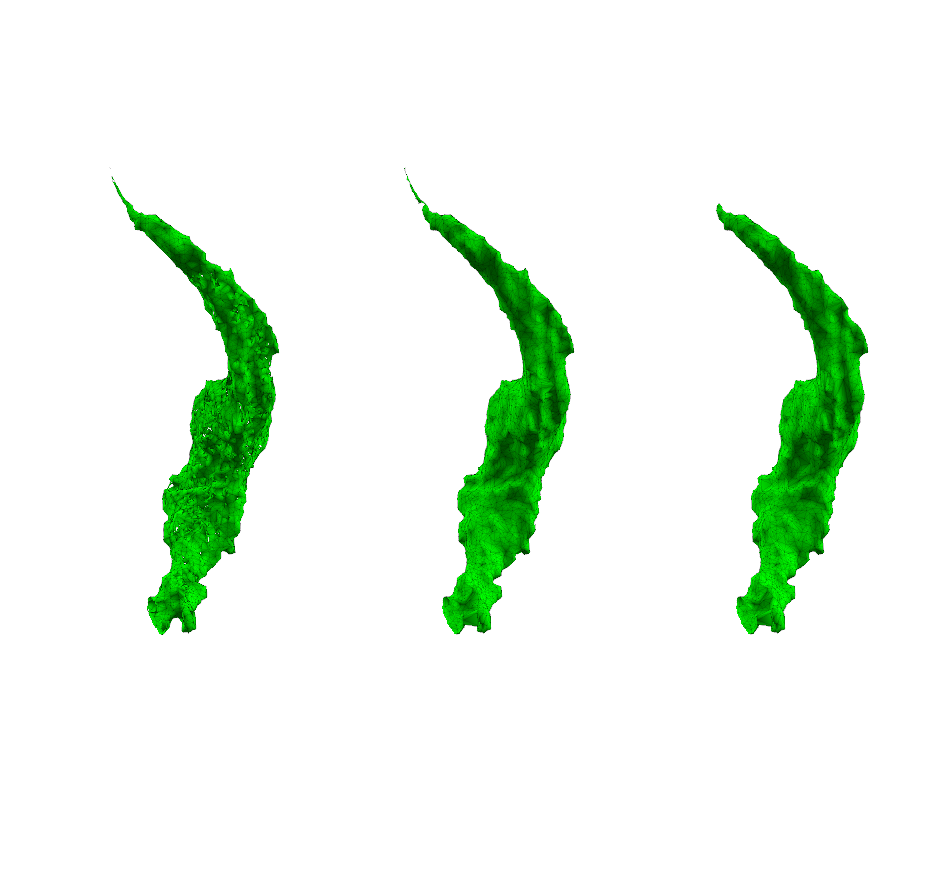

ax = plot_cell_meshes(mt);
set(ax,'View',[-45 0])

#### update meshT

meshT(meshT_row,:) = mt;

### `TB2_T2C-03_cw`

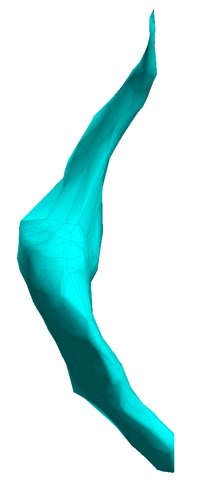

`Reconstruction looks too simplistic. `Calling alphaShape with an alpha radius of 0.5 greatly improves the reconstruction. MP looks like the best method.

cellName = "TB2_T2C-03_cw";
[mt, meshT_row] = generateSingleCellMesh(VL,meshT,paths, cellName, 1, 0.5);

            Cell             Type     Health      Method    Polarity    AlphaRadius    VolAS    VolMP    VolFX 
    _____________________    ____    _________    ______    ________    ___________    _____    _____    ______

    "TB1_IMMCell09_CM_ry"    "IV"    "healthy"     "fx"        1            NaN        98.73    102.5    350.13

            Cell             Type     Health      Method    Polarity    AlphaRadius    VolAS    VolMP    VolFX 
    _____________________    ____    _________

#### Display results

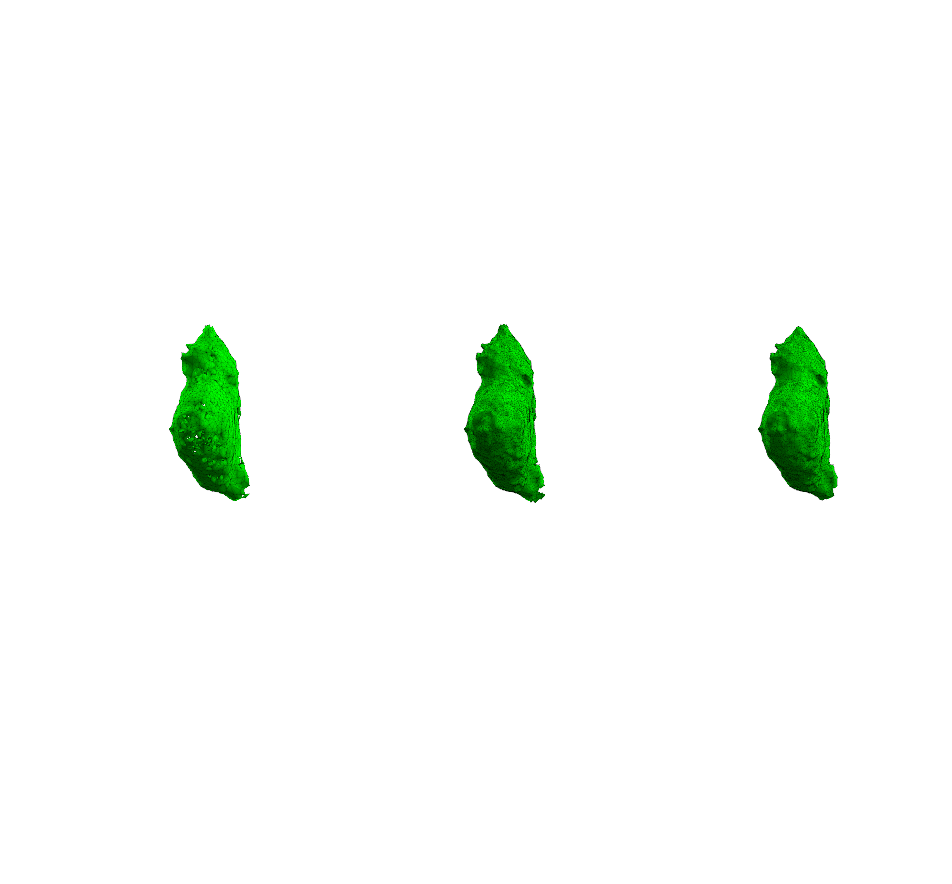

ax = plot_cell_meshes(mt);
set(ax,'View',[-45 0])

#### update meshT

meshT(meshT_row,:) = mt;

### `TB1_IMMCell09_CM_ry`

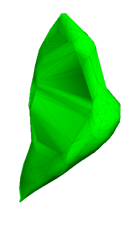

`Reconstruction looks too simplistic. `Calling alphaShape with an alpha radius of 0.5 greatly improves the reconstruction. FX looks like the best method here

cellName = "TB1_IMMCell09_CM_ry";
[mt, meshT_row] = generateSingleCellMesh(VL,meshT,paths, cellName, 1, 0.5);

#### Display results

ax = plot_cell_meshes(mt);
set(ax,'View',[-45 0])

mt.Method = "fx";
meshT(meshT_row,:) = mt;

### Save meshT

save(meshT.Properties.UserData.filePath,"meshT")

## Capture Cell Metrics (create cellT)

### load meshT

if needed

load(fullfile(paths.cellMesh,"meshT.mat"),"-mat","meshT")

### Update Cell names

replace two of the dying cells meshes with their more complete versions that include the "bits", or apical ends. These meshes were generated using the [generate_dyingMesh_dyingT](matlab:open('./generate_dyingMesh_dyingT.mlx')) script and copied into the cell mesh folder.

meshT.Cell = replace(meshT.Cell,"TB2_TCdying-01_cw","TB2_TCdying01");
meshT.Cell = replace(meshT.Cell,"TB2_TCdying-02_cw","TB2_TCdying02");

### Create cellT table

This table, in conjunction with the ***dyingT*** table, will be used to analyze the cell metrics

cellT = calcCellMetrics(meshT);

#### update cellT properties

cellT.Properties.UserData.filePath = fullfile(paths.lysosome,"cellT.mat");
cellT.Properties.UserData.meshPath = paths.cellMesh;
cellT.Type = categorical(cellT.Type);
cellT.Health = categorical(cellT.Health);
type = cellT.Type;
type(cellT.Health=="early") = 'ed';
type(cellT.Health=="late") = 'ld';
cellT.PlotSort = categorical(type,{'IV','III','II','I','ld','ed'},'ordinal',true);

#### save cellT to lysosome folder

save(cellT.Properties.UserData.filePath,"cellT");

# Local Functions

function meshT = generateCellMeshes(VL, paths)
%GENERATECELLMESHES Generate Surface Meshes from which cell volumes will be
%calculated. For each cell, three different meshes will be created: AS, MP,
%FX, each representing a different stage in mesh generation. AS, or
%AlphaShape represents the first stage of mesh generation. This mesh is
%representative of cell morphology but may containing numerous holes in surface, 
% leading to miscalculation of volume. MP, or manifoldPlus, is the first attempt to 
% repair any holes found in the surface. FX, or pymeshfix, is the final
% attempt to repair holes. This version may be more ragged looking than AS
% but more watertight. 
%
% OUTPUT:
%   meshT: table containing the following fields
%          - Object: ID of Cell
%          - VolAS, VolMP, VolFX: calculated volumes from each mesh stage.
%          - Method:  used to indicate which mesh is the most representative of the cell

% generateCellMeshTable

arguments
    VL table % vertices list table
    paths struct % structure containing project relevant paths
end

    idT = VL.Properties.UserData.idT;

if exist(fullfile(paths.cellMesh,"meshT.mat"),'file') % start with meshT
    fprintf('meshT file found and loaded. Using this table for the analysis.')
    load(fullfile(paths.cellMesh,"meshT.mat"),"-mat","meshT")
    meshT{:,{'VolAS','VolMP','VolFX'}} = nan(height(meshT),3);
    count=height(meshT);
else
    idT = sortrows(idT,["Type","Health"]);
    meshT = idT(:,{'Cell','Type','Health'});
    count=height(meshT);
    meshT.Method = repmat("mp",count,1);
    meshT.Polarity = ones(count,1);
    % meshT = movevars(meshT,{'Method','Polarity'},'After','Mesh');
    meshT = [meshT array2table(nan(count,4),'VariableNames',["AlphaRadius","VolAS","VolMP","VolFX"])];
end

hwb = waitbar(0,"Please Wait");
for n=1:count
    mesh_name = meshT.Cell(n);

    % get trace vertices
    vCell = getVertsAndAlign(VL, mesh_name,meshT.Polarity(n)); % align point clouds to axes

    % calculate alphaShape and then surface mesh object
    if isnan(meshT.AlphaRadius(n))
        shp = alphaShape(vCell); % no alpha radius inputted - the default
    else
        shp = alphaShape(vCell,meshT.AlphaRadius(n));
    end

    [volMP, volFX] = getWaterTightMesh(shp,mesh_name, paths);

    meshT.VolAS(n) = shp.volume;
    meshT.VolMP(n) = volMP;
    meshT.VolFX(n) = volFX;
       
    waitbar(n/count, hwb,sprintf('%d. %s',n,mesh_name))

end

la = meshT.VolAS > meshT.VolFX;% volumes that get smaller indicate increase in raggedness in surface
meshT.Method(la) = "as"; % so, just use the alphaSurface
% meshT.Properties.UserData.path = fullfile(paths.cellMesh,"meshT.mat");
meshT.Properties.UserData.filePath = fullfile(paths.cellMesh,"meshT.mat");
meshT.Properties.UserData.meshPath = paths.cellMesh;
meshT.Properties.UserData.fdec = ["as" "mp" "fx"]; %as=alphaShape, mp=manifoldPlus, fx=meshFix
meshT.Properties.UserData.ext = ".obj";
delete(hwb)
end



## Generate Single Cell Mesh

Note: works only for VL with lysosome data in it (because of **getVertsAndAlign**)

function [mt, srow] = generateSingleCellMesh(VL,meshT,paths, cellName, Polarity, AlphaRadius)
%GENERATECELLMESH Generates meshes for the selected mesh.  Assumes VL contains lysosome structures

arguments
    VL table % vertices list
    meshT table  % meshT table with info regarding cell to reconstruct
    paths struct % paths structure
    cellName {mustBeText}
    Polarity {mustBeNumeric,mustBeScalarOrEmpty}
    AlphaRadius {mustBeNumeric,mustBeScalarOrEmpty}
end

srow = find(meshT.Cell==cellName);
mt = meshT(srow,:);
disp(mt)
mt.Polarity = Polarity; % flip cell up
mt.AlphaRadius = AlphaRadius; % increase to close hole

vCell = getVertsAndAlign(VL, mt.Cell,mt.Polarity);

% calculate alphaShape and then surface mesh object
if isnan(mt.AlphaRadius)
    shp = alphaShape(vCell); % no alpha radius inputted - the default
else
    shp = alphaShape(vCell,mt.AlphaRadius);
end
[volMP, volFX] = getWaterTightMesh(shp,mt.Cell, paths);
mt.VolAS = shp.volume;
mt.VolMP = volMP;
mt.VolFX = volFX;
disp(mt)
end

## Plot Meshes

function ax = plot_cell_meshes(mt)

meshFolder = mt.Properties.UserData.meshPath;
fdec = mt.Properties.UserData.fdec;
ext = mt.Properties.UserData.ext; % .obj

mmfig;
tiledlayout(1,3,"TileSpacing","none","Padding","tight")
for n=1:3
    fullpath = fullfile(meshFolder, mt.Cell+ "_" + fdec(n) + ext);
    mesh = readSurfaceMesh(fullpath);
    ax(n) = nexttile;

    plotCellMesh(mesh,'g')
end

linkaxes(ax)

end

## Overlay Meshes using Patch

function hp = overlayCellMeshes(paths, object)
% meshT.Object(mt_row)

contents = dir(fullfile(paths.cellMesh,object+"*.obj*"));
mmfig;

mesh = readSurfaceMesh(fullfile(paths.cellMesh, contents(1).name));
hp(1) = patch(Faces=mesh.Faces,Vertices=mesh.Vertices, ...
    FaceColor='c', ...
    FaceAlpha = 0.5,...
    edgeAlpha = 0.2);
hp(2) =  patch(Faces=mesh.Faces,Vertices=mesh.Vertices, ...
    FaceColor='m', ...
    FaceAlpha = 0.75,...
    edgeAlpha = 0.2);
axis equal off
end